% clc; clear variables; close all
working_directory = 'C:\Users\haffnerf\WORKSPACE\nir-lab\2- Data-driven XAI - PyTorch';

% Load functions from the matlab directory
addpath(genpath(append(working_directory, 'matlab')));

% This script is fed by the full range dataset, % although it generates the reduced range dataset later 
% during the pre-processing stage.
data = append(working_directory, '\data\cetanes\raw-kennard-reduced_range.mat');
load(data)

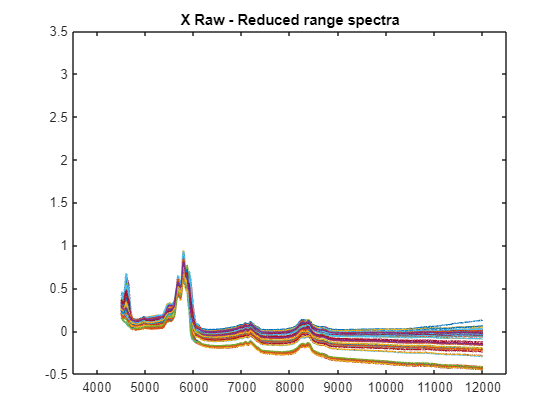

X = cat(1, X_train, X_test);
figure;
plot(W, X');
xlim([3500 12500]);
ylim([-.5 3.5]);
title(['X Raw - Reduced range spectra']);

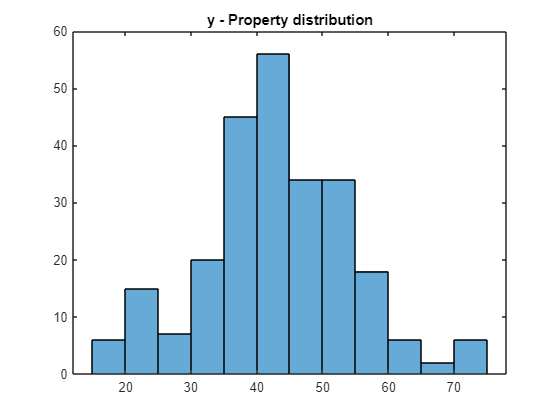

Y = cat(1, y_train, y_test);
figure;
histogram(Y');
title(['y - Property distribution']);

yMax = max(Y)

yMax = 71.1000

yMin = min(Y)

yMin = 19

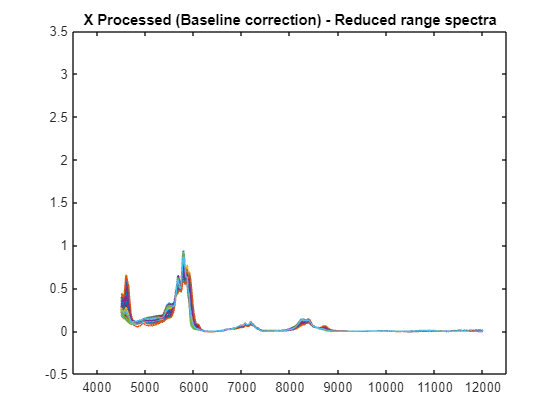

baseline_corr_order=2;
baseline_options=[];
[X_train_corr, allb, a] = wlsbaseline(X_train, baseline_corr_order, baseline_options);
[X_test_corr, allb, a] = wlsbaseline(X_test, baseline_corr_order, baseline_options);
figure;
plot(W, X_train_corr');
xlim([3500 12500]);
ylim([-.5 3.5]);
title(['X Processed (Baseline correction) - Reduced range spectra']);

% nbfact = 6;
% y_hat = pls_nipals_pred(X_train_corr, y_train, nbfact, 1, X_test_corr);
% residual = y_test - y_hat;
% rmsep = RMSEP(y_test, y_hat);
% r2 = r_squared(y_test, y_hat);

ncomp = 6;
[XL,yl,XS,YS,beta,PCTVAR,MSE,stats] = plsregress(X_train_corr, y_train, ncomp);

'plsregress' requires Statistics and Machine Learning Toolbox.

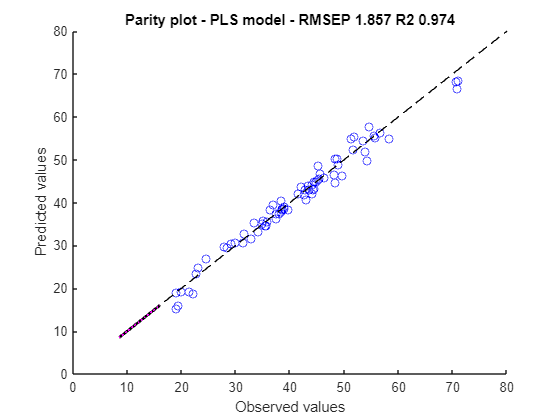

% Je comprends pas à quoi ça sert... ?!
x_aux=[8.5,16]; R=[0.07,0.07];
ICR1=x_aux+(R./1.41) ; ICR2=x_aux-(R./1.41) ;

% Figure scale ]10,80[
figure; hold on;
n_test = size(X_test, 1);
%affiche le marker avec une couleur proportionnelle à la valeur de y
% icolor=round(rscalex(residual,1,64));
% couleur=pink;
for ical=1:n_test
    plot(y_test(ical),y_hat(ical),'ob');
%     text(Y(ical),y_hat(ical), int2str(ical));
end
line([10 80],[10 80], 'Color','black','LineStyle','--')
plot(x_aux, x_aux,'k','LineWidth',2);
plot(x_aux, ICR1,':m','LineWidth',1);
plot(x_aux, ICR2,':m','LineWidth',1);
xlabel('Observed values');
ylabel('Predicted values');
title(['Parity plot - PLS model - RMSEP ' num2str(round(rmsep,3)) ' R2 ' num2str(round(r2,3))]);

[tcal,pcal,btcal,bX,RMSEcal,SRcal,levcal,wgcal]=fwFPLS(X_train_corr, y_train, nbfact);

fitting_ratio = round((rmsep/RMSEcal),3)

fitting_ratio = 1.0130

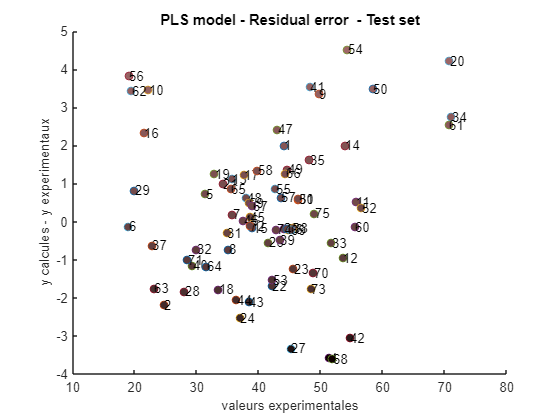

% Residual graph - test_set
figure; hold on;
%affiche le marker avec une couleur proportionnelle à la valeur de y
icolor=round(rscalex(residual,1,64));
couleur=pink;
for i=1:n_test
    plot(y_test(i), residual(i), 'o', 'MarkerFaceColor', couleur(icolor(i),:));
    text(y_test(i), residual(i),num2str(i));
end
xlabel('valeurs experimentales','fontsize',10);
ylabel('y calcules - y experimentaux','fontsize',10);
title(['PLS model - Residual error  - Test set']);

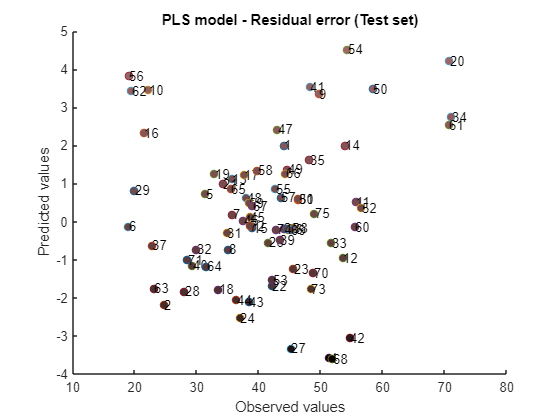

% Residual graph - train_set
figure; hold on;
icolor=round(rscalex(residual,1,64));
for ical=1:n_test
    plot(y_test(ical),residual(ical),'o','MarkerFaceColor',couleur(icolor(ical),:));
    text(y_test(ical),residual(ical), int2str(ical));
end
xlabel('Observed values');
ylabel('Predicted values');
title(['PLS model - Residual error (Test set)']);

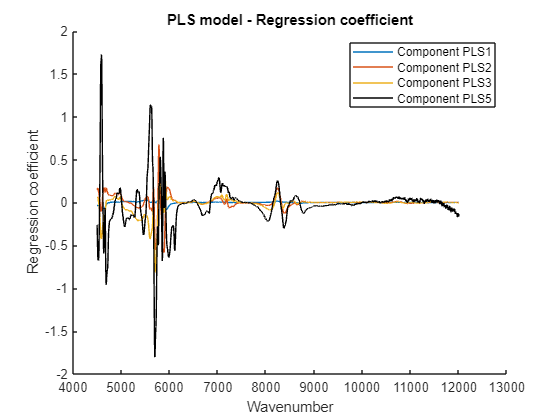

% Regression coefficient
figure; hold on;
plot(W,pcal(:,1));
plot(W,pcal(:,2));
plot(W,pcal(:,3));
plot(W,pcal(:,5),'k');
xlabel('Wavenumber');
ylabel('Regression coefficient');
legend('Component PLS1','Component PLS2','Component PLS3','Component PLS5');
title(['PLS model - Regression coefficient']);